%%create datastore for all images and split into training,validation,and testing data
root = fullfile('M:\Documents\MATLAB\BME3503C\Final_Project\archive');
MRIs = imageDatastore(root,'IncludeSubFolders',true,'LabelSource','foldernames');
[train, val, test] = splitEachLabel(MRIs, 0.7,0.1,0.2, 'randomized');

%%resize images and preprocess
imageSize = [227 227 3];
autrain = augmentedImageDatastore(imageSize,train,'ColorPreprocessing', 'gray2rgb');
auval = augmentedImageDatastore(imageSize,val,'ColorPreprocessing', 'gray2rgb');
autest = augmentedImageDatastore(imageSize,test,'ColorPreprocessing', 'gray2rgb');
[data,info]=read(autrain);
[data,info]=read(autest);


%%create variable to store trained network and results
load net.mat;

%%calculate accuracy of model on test set
YPred = classify(net,autest);
YValidation = test.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.9412

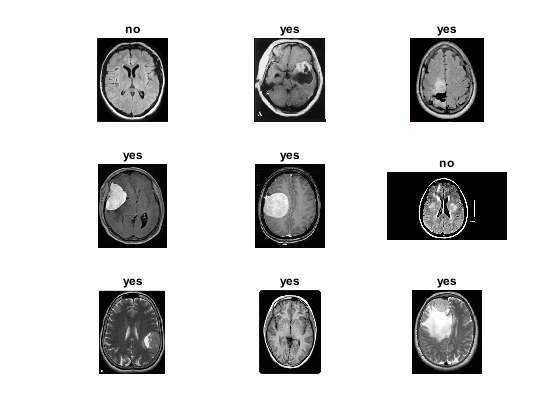

%%Show sample images with their predicted labels from the model

ii = randi(numel(test.Labels),1,9);

figure()
for i = 1:numel(ii)
    subplot(3,3,i)
    I = readimage(test,ii(i));
    label = YPred(ii(i));
    
    imshow(I)
    title(label)
end

%%visualize deep learning network
% analyzeNetwork(net);
figure
I = deepDreamImage(net,root,2)

Error using deepDreamImage (line 153)
Layer 'M:\Documents\MATLAB\BME3503C\Final_Project\archive' does not exist.

imshow(I)